## RRT

% parking lot costmap generation for real world parking lot
parking_spot = 4;
road_file_path = 'ParkingLotGeneration/ParkingLines/polylines9.shp';
parking_points_file_path = 'ParkingLotGeneration/ParkingSpots/points6.shp';
car_width  = 0.000005;
car_length = 0.00002;
road_f = shaperead(road_file_path);
points_f = shaperead(parking_points_file_path);
info = shapeinfo(road_file_path);
boundary_bounds = info.BoundingBox;
min_col = boundary_bounds(1, 1);
min_row = boundary_bounds(1, 2);
max_col = boundary_bounds(2, 1);
max_row = boundary_bounds(2, 2);
cost_map = parking.costmap(road_f, max_row, min_row, max_col, min_col);
% cost_map = vehicleCostmap(costmap);

Currently, this rrt algorithm does not generate equidistant path segments, if it is needed, we can modify the random method.

I'm also not using vehicleCostmap object anymore because I was having some problem with it. 

startPos = int64([0,0,0]); %x,y,theta (radians)
goalPoses = {[100,100,pi/4]};
minTurning = 10; %in meters
iterations = 2000;

% Matlab parking valet inputs
ws = load('input_variables_from_matlab_parking_example.mat');
startPos = ws.currentPose;
costmap = ws.combinedMap;
minTurning = 4;
routePlan = ws.routePlan;
goalPoses = num2cell(routePlan.EndPose, 2);
iterations = 2000;

figure
hold on
for i = 1:length(goalPoses)
    tree = rrt(costmap, iterations, startPos, goalPoses{i}, minTurning);
    [path, Tree]= run(tree);
%     %if path is empty (i.e. did not find a path in last run), run again
%     %will fix this later
%     for i = 1: length(path)
%         disp(path{i});
%     end
    [X1, Y1, ~] = convert_cell_vector_to_double_vectors(path);
    plot(Y1, X1);
    startPos = goalPoses{i};
end

    51   122

   10   70

   59   28

   61    8

    58   126

   50   66

   15    4

    76   119

   29   17

    38   124

    84   100

    96   141

   11   97

   48   10

   90   75

   77    9

   26   98

   13   96

    38   115

   65   57

   30   51

   92   68

   44   68

   95   33

   88    3

    34   115

   34   93

   45    2

   60   90

   65   51

    49   105

   89    8

   10   97

    76   148

   13   55

   68   56

   86   44

    13   101

    20   130

   75   63

    1   22

    27   131

   60   48

   28   65

    90   139

   51   94

   72    4

   57    7

   42   70

    2   10

   92   80

   37   55

   15   22

   35   50

   78   73

   46   20

    89   101

   84   98

    98   147

   25   94

   73   75

   85   29

   12    1

   15   80

   51   58

   31    1

   82   96

   45   37

    80   124

   85   70

    97   126

    8   36

   82   61

    47   143

    97   115

    57   137

   50   25

   33   44

   56   10



    7   25

    95   122

    71   146

   100   148

    15   144

   53   11

    31   134

   83    1

    64   120

   25   10

   26   15

   48   63

    38   133

   42   43

    5   33

   24    4

   70    1

   61   61

   25   98

   32   16

   54   25

    88   100

    85   114

   81   95

    71   103

   32   80

   87    8

   50   65

   90   95

   98   88

   84   70

   55   27

    63   144

   53   72

   79   14

   88    1

    51   102

   57   72

   32   90

    91   102

   95   15

   51   17

    55   103

    15   117

    40   135

   31    9

   22   12

   95    2

   11    2

   22    2

   64   78

   25   29

    9   55

    1   90

   48   46

    74   126

   26   77

   45   51

    84   147

   63   27

   12   87

   33   40

   55   27

   68    8

    3   43

     8   135

   85   59

   17   65

    42   109

    41   143

    91   143

   35   44

   89   32

   13   78

   91   60

   22   12

   93   90

    38   100

   79   50

   69 

   24   43

   17   49

   80   45

   78   83

    55   110

    77   135

    14   119

   19    4

   13   20

    13   140

    27   141

    64   131

   37   35

   19   82

   26   46

    2   88

    96   127

    1   95

   36   17

   54   62

    52   133

   15   65

    6   57

   72   14

   67   44

   60   23

   44    2

   23   40

   51   32

    35   112

   41    8

   39   71

   83   46

   82   85

    5   39

   59   72

   20   36

   78   93

    14   107

   40   69

   71   60

    1   11

   59   67

   93   14

   38   82

    11   136

    63   136

   63    2

   32   17

   63    9

   67   72

   31   77

    71   122

   32   47

    34   100

    86   114

    88   131

    17   128

    96   116

   88   10

   65   49

    64   132

    37   115

   17   78

    63   107

   31   40

   92   92

    9   94

    19   117

   86   50

    14   115

   32   38

   20   10

   55   61

   75   73

   38    9

   21   82

    41   135

    6   67

   5

    6   93

   69   45

   57   47

   81   55

   70   95

   96   30

   60   13

    54   127

    4   49

    71   129

    50   149

   43   40

   47   24

   16   40

   76   91

    97   116

   57   68

    29   113

    9   16

   73   53

   58   45

   71   54

    72   149

    8   70

     9   109

   91   13

   52   83

   69   45

   60   30

    66   105

   46   24

   42   89

    32   125

   12   38

   94   98

    75   122

    5   62

   73   21

   63   37

    84   126

   45   59

   96    1

   40   73

   62   11

   14   98

   22   18

    4   25

    51   130

   77   20

     6   101

   48   74

   31   49

   91   68

   75   28

    8   31

   56   99

   94    6

   16   66

   33   13

   81   60

   66   85

    1   98

   32   40

   46   93

   80   84

     2   119

    27   123

   69   91

   39   10

   100    99

   23   14

    24   135

   22   72

   91   29

   45   93

    59   100

   27   64

    80   140

   47   46

   44   46

  

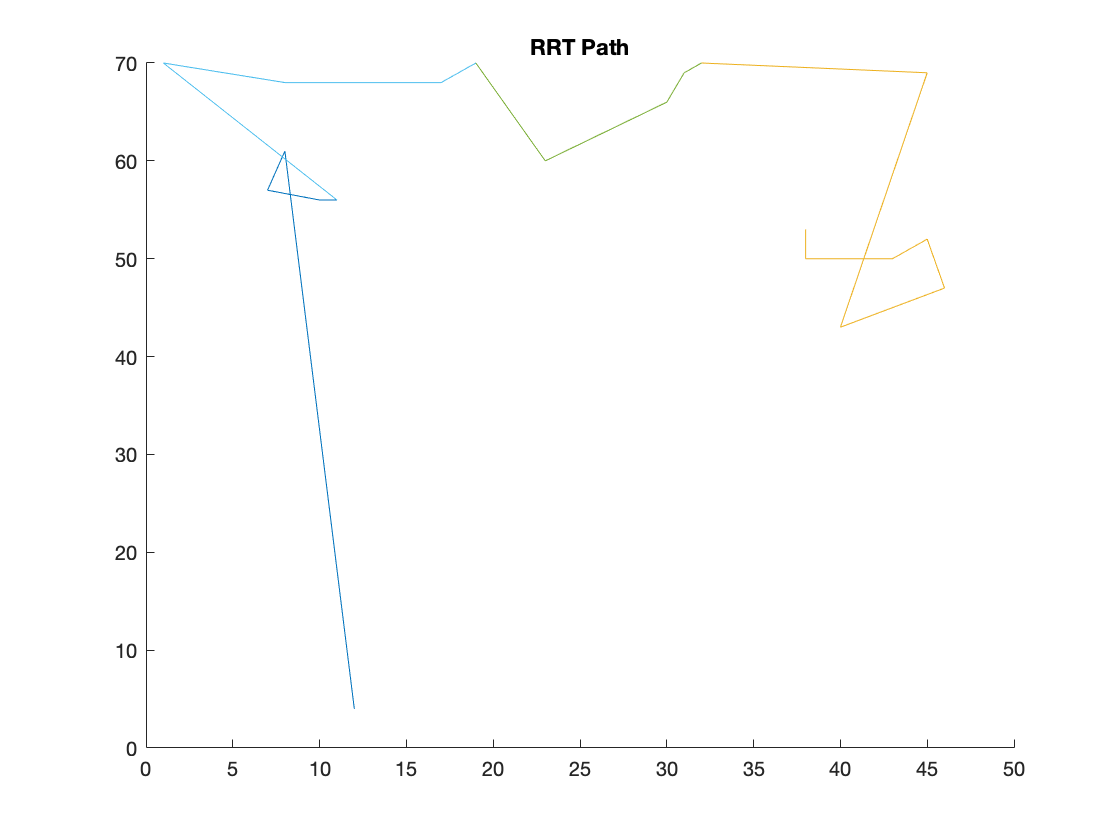

title('RRT Path')
hold off

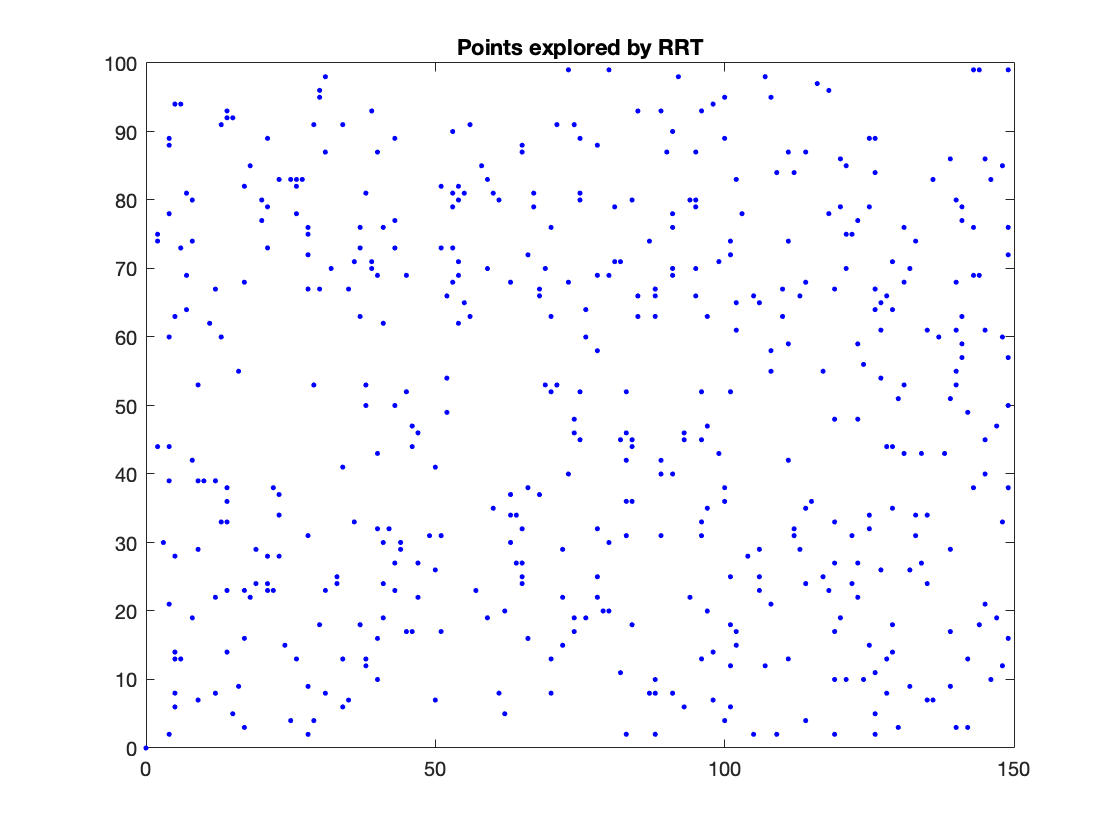

[X, Y, Theta] = convert_cell_vector_to_double_vectors(tree.nodes);
figure
plot(Y, X, 'b.')
title('Points explored by RRT')

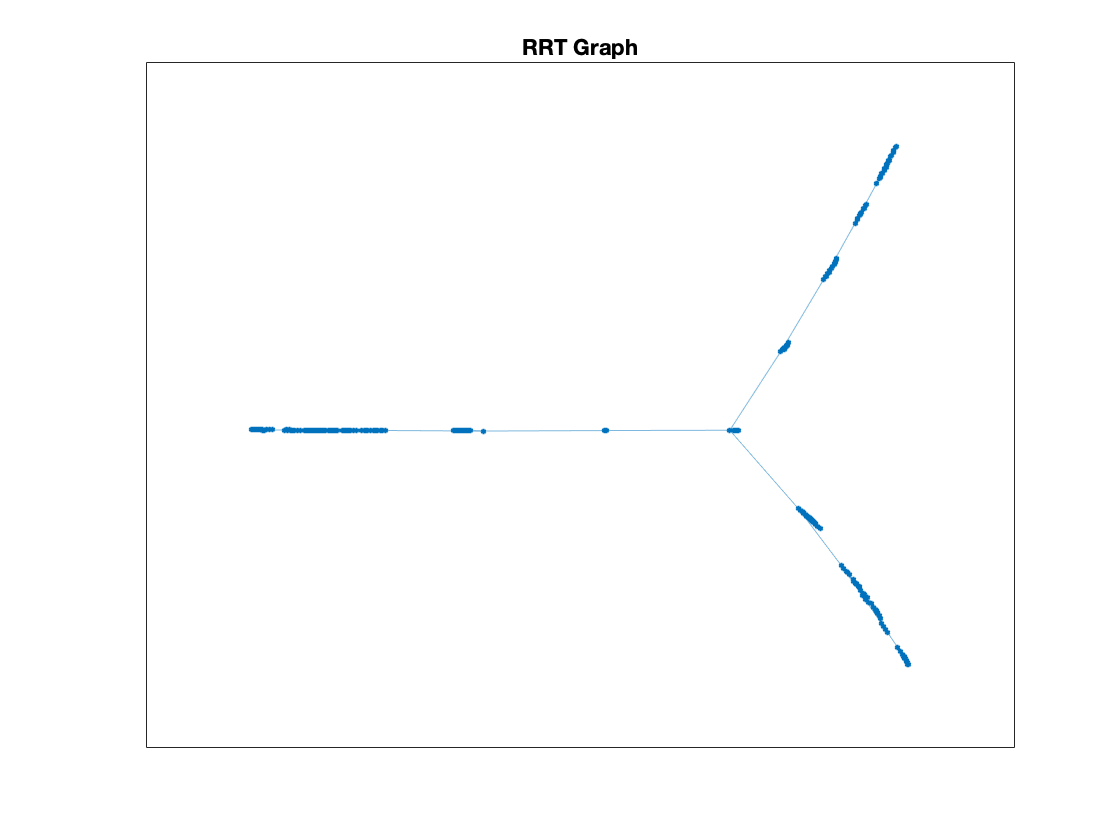

G = graph(tree.s, tree.t, tree.weight);
plot(G);
title('RRT Graph')

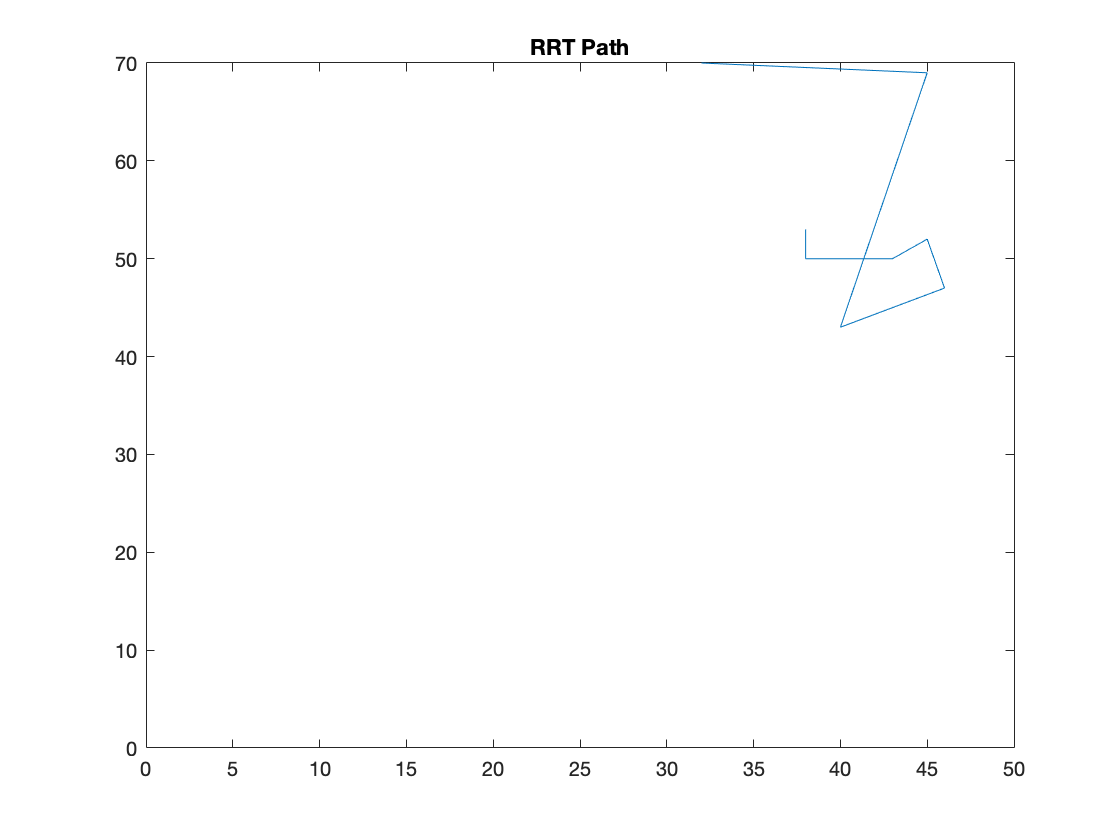

[X1, Y1, Theta1] = convert_cell_vector_to_double_vectors(path);
figure
plot(Y1, X1)
title('RRT Path')

%% Processing for plotting, should we just change the data structure itself
% this way?? Open Question...

function [X, Y, Theta] = convert_cell_vector_to_double_vectors(data)
    size = length(data);
    X = zeros(size);
    Y = zeros(size);
    Theta = zeros(size);
    for i = 1:size
        n = data{i};
        X(i) = n(1);
        Y(i) = n(2);
        Theta(i) = n(3);
    end
end
%%reference link:
%https://github.com/Mayankm96/Motion-Planning-GUI/blob/master/GUI/RRTree/RRT.m
